# Getting Started

## Preprocessing

Create object EMG data.

NB: data is a struct as defined in the Data Requirements.

Use the `getInfo` function to extract info about the experimental protocol of the data collected. Those info need to be stored in the data structure. Edit the `getInfo` function to make the data structure compatible with the toolbox.

load('data.mat');
info = getInfo(data);

Define the options to build the synergy analyzer object.

par.type = 'EmgKinData';
par.chlabels = [emgchannels(:)', kinchannels(:)'];
par.order = 2; %determines the order of the kinematic derivatives (0->position, 1->velocity, 2->acceleration) 
par.delay = -0.05; %50ms -> KIN data were anticipated of 50 ms to account for an estimated electromechanical delay between EMG and KIN (Scano et al. 2022)

Create the synergy analyzer object. With `opt.verbose = 1` details of the processing will be printed in command window.

sa = SynergyAnalyzer(data,info,par);
sa.opt.verbose = 1;

Filter and resample EMG and KIN data.

sa.opt.emgFilter.type = 'fir1';
sa.opt.emgFilter.par = [50 20/(1000/2)];  % 20 Hz @ 1KHz EMG sampling rate
sa.opt.emgFilter.resample = 1;
sa.opt.emgFilter.resample_period = .01; % resampling period [s]

sa.opt.kinFilter.type = 'butter';
sa.opt.kinFilter.par  = [2 10/(100/2)]; %2 order 10Hz @ 100Hz sampling rate
saf = sa.dataFilter;

Plot sample of filtered EMG and KIN data

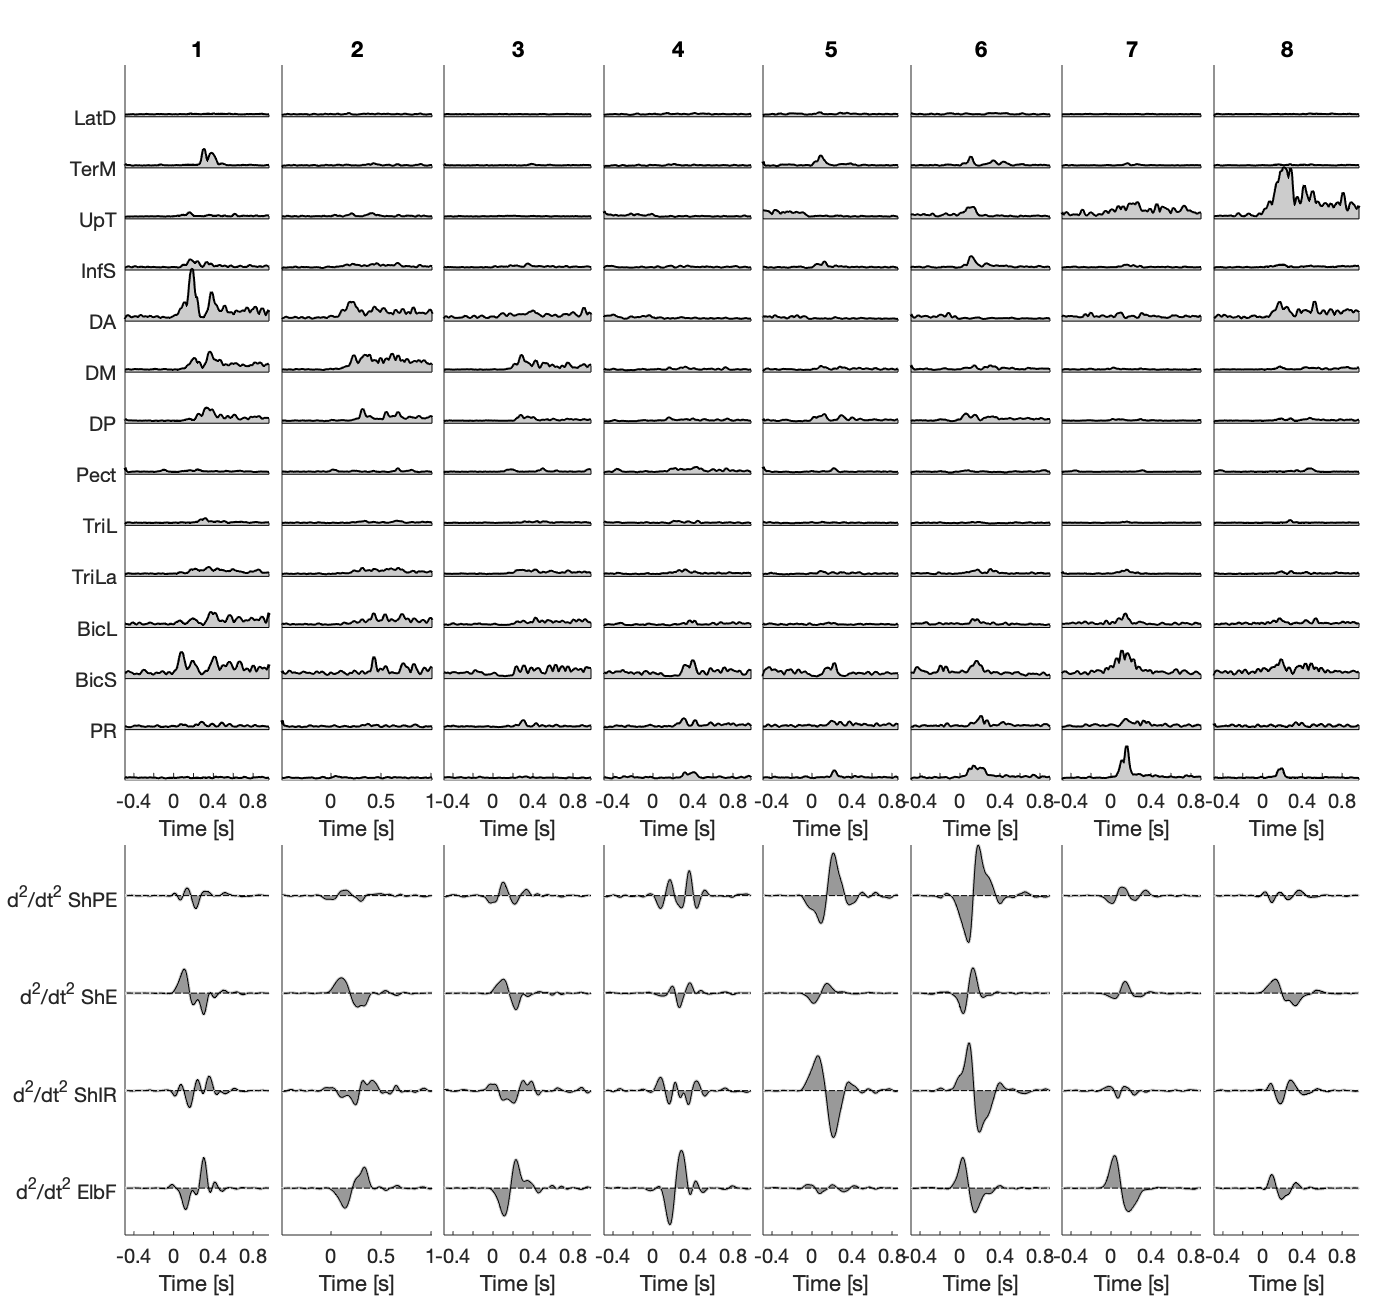

opt.fill = 1;
opt.figure = figure('NumberTitle','off','Name','Filtered EMG and KIN data',"Position",[0 0 700 650]);
plot(saf.data(1:8),opt) % frontal plane, 8 directions

Get phasic activity by subtracting tonic activity of the EMG signals.

saf = saf.emgPhasic;

Average data in groups of trials within same experimental condition. Define the common time range.

saf.opt.average.gr = saf.groupTrials('type3',[1:8]' );  % type3 is the target number  
saf.opt.average.trange = [-.3 .7]; % time interval in s before and after onset for averaging
sav = saf.average;

Normalize EMG and KIN data to the max of each channel. 

EMG are normalized between 0 and 2. KIN are normalized between -1 and 1.

sav.opt.normalize.type = 32;
sav.opt.normalize.nonnegch = sav.data(1).nonnegch;
sav = sav.normalize;

Plot a sample of averaged and normalizes EMG and KIN data

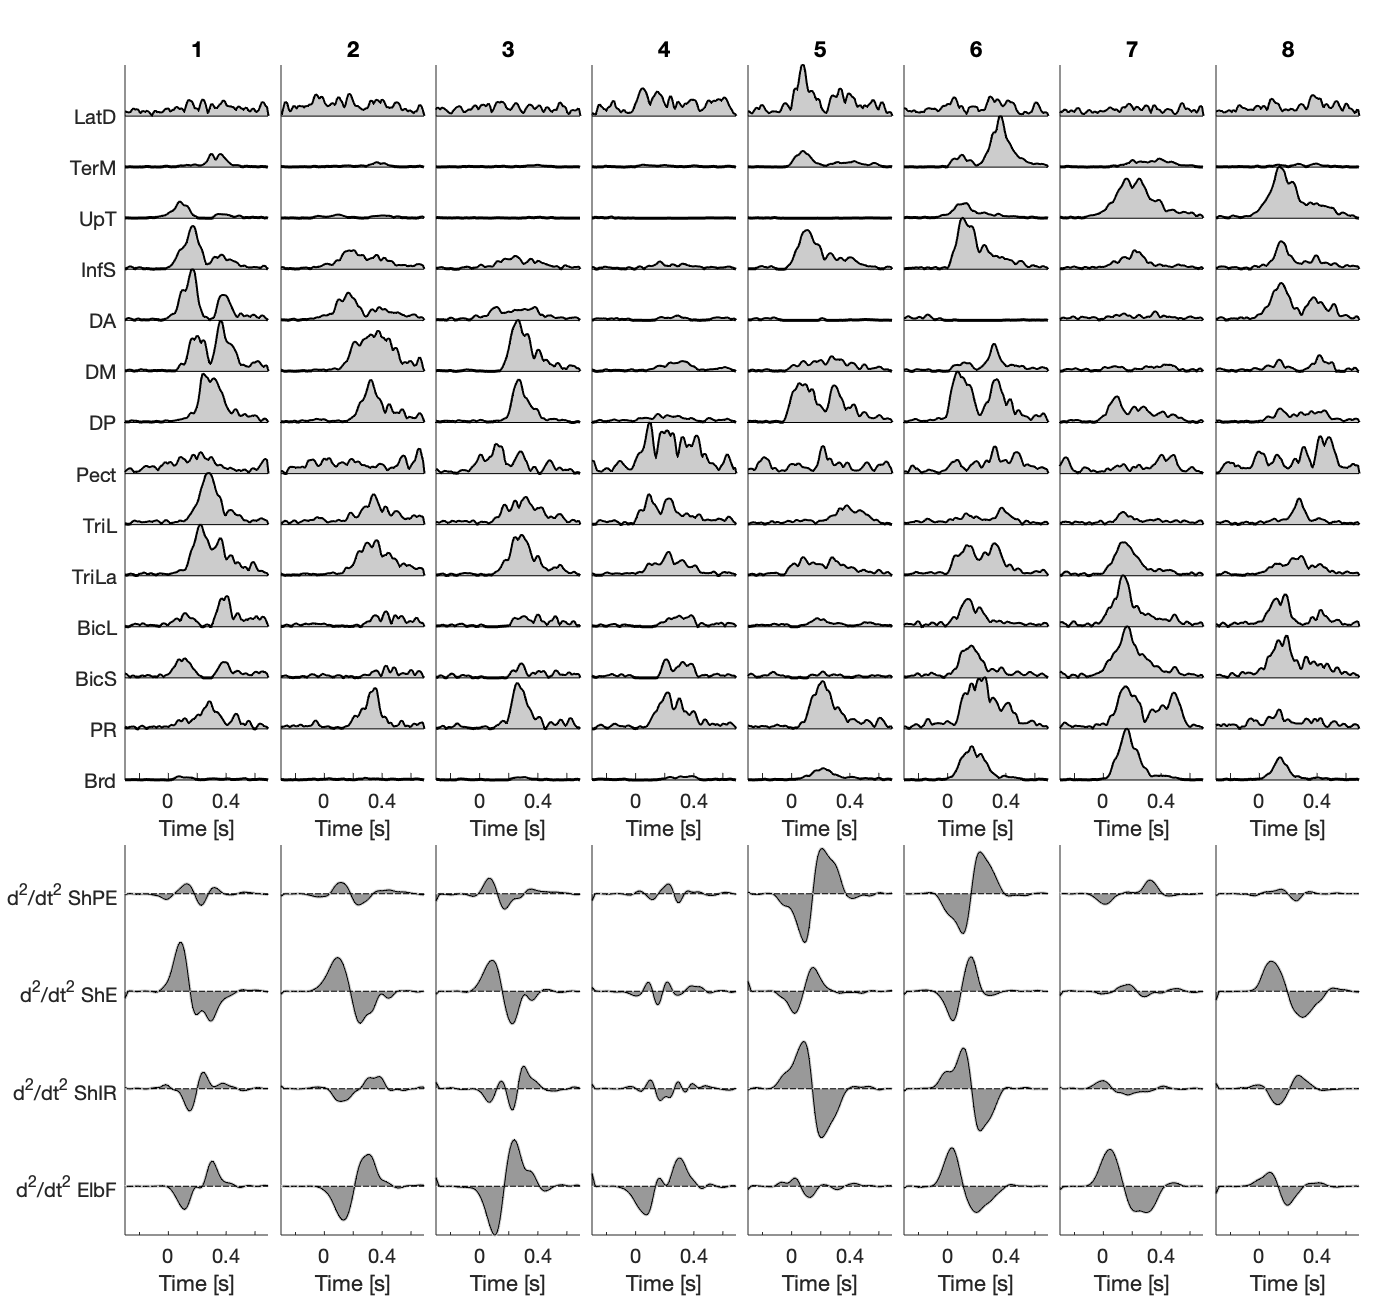

opt.figure = figure('NumberTitle','off','Name','Normalized EMG and KIN data',"Position",[0 0 700 650]);
plot(sav.data(1:8),opt)

## Synergy Extraction

Define parameters for the extraction

sav.opt.find.algo = 'mmf';
sav.opt.find.N = [1:14];
sav.opt.find.nrep = 10;
sav.opt.find.niter = [100 10 10^-6 10000];
sav.opt.find.plot = 0;

Extract synergies

s1 = sav.find;

Plot $R^2$ curve for the best repetition of each set of synergies

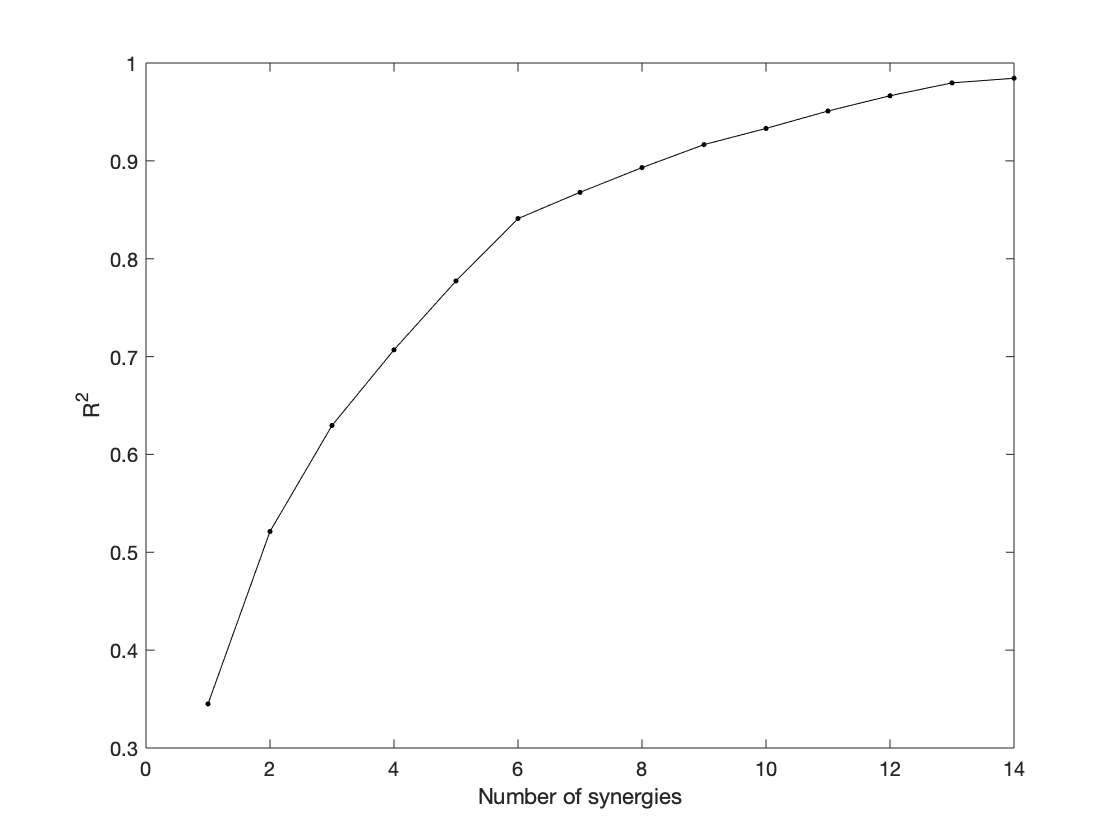

s1.opt.plot.type = 'rsq';
plot(s1)

Select the number of synergies according to the default method, which chooses the first set that has an $R^2$ larger than 0.8 and plot the selected set of synergies, i.e. `N = 6.`

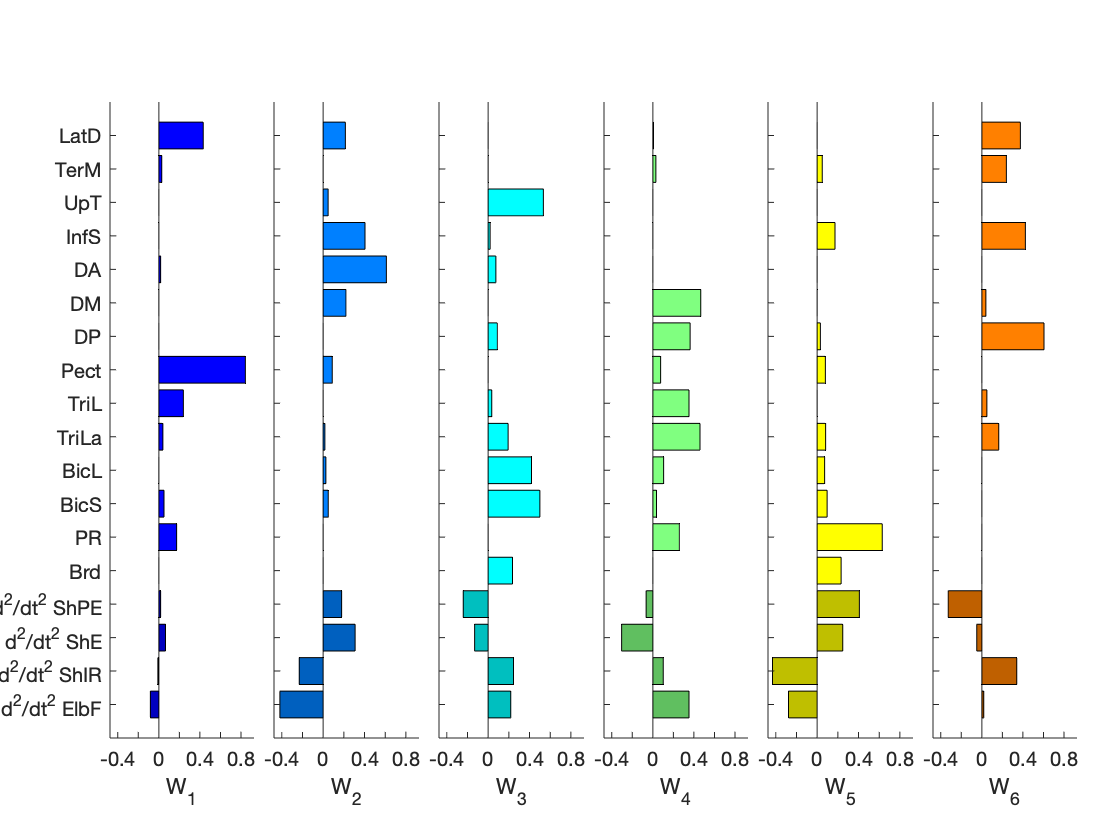

Nsel = numsel(s1.syn);
s1.opt.plot.N = Nsel;
s1.opt.plot.type = 'W';
plot(s1)

Plot original data and reconstructed data based on the synergy set chosen. The reconstructed signals are the black thick lines.

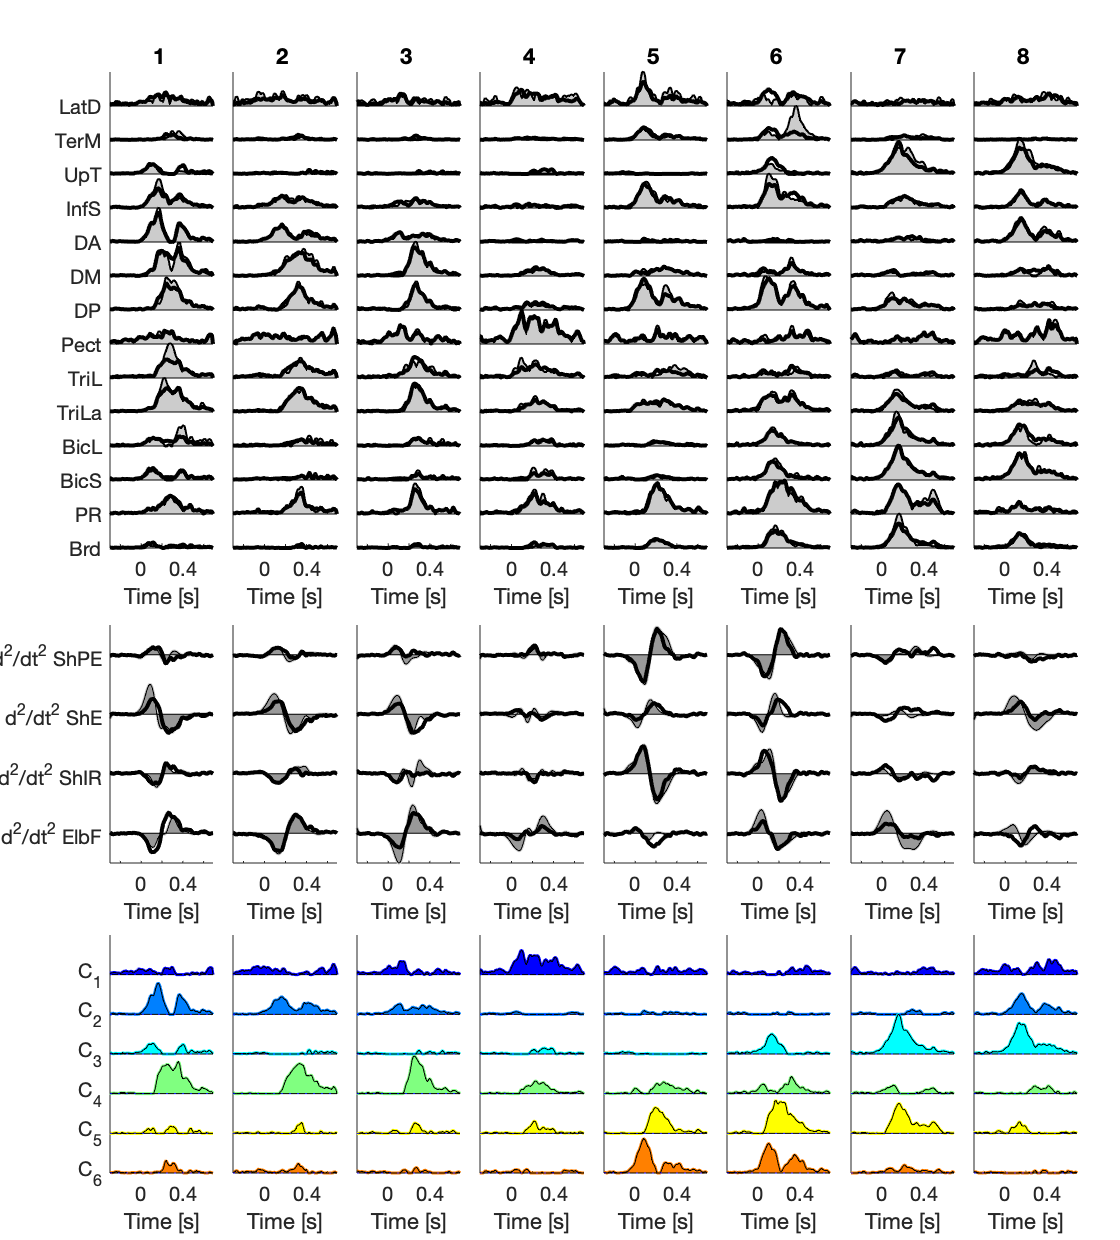

s1.opt.plot.type = 'rec';
s1.opt.plot.isect = [1:8];
plot(s1)